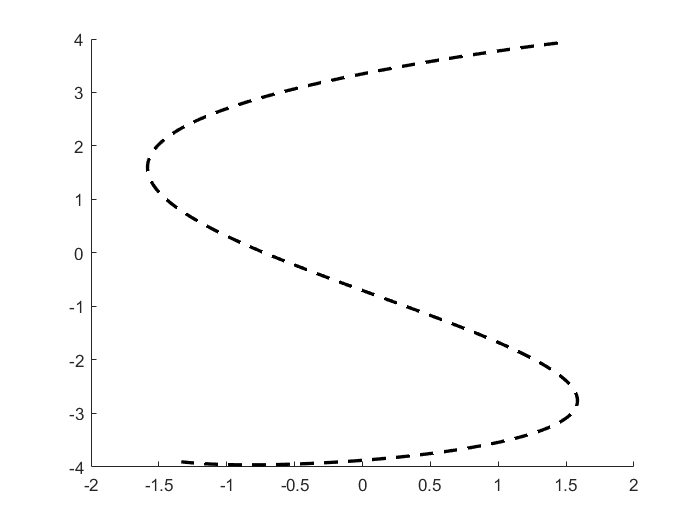

clc, clear all
%%plot stuff
beta = 0.2;
diam = 0.235;
Npts = 10;
t_max = 3.2 / beta;
T = linspace(0, t_max, t_max*Npts);
U = T .* beta;
R = 4.*[0.3960*cos(2.65*(U+1.4)) ; -0.99*sin(U+1.4)];
clf
hold on
plot(R(1,:), R(2,:),'k--', "Linewidth", 2)

%plot(R(1,:), R(2,:),'.', "Markersize", 10)
%%symbolic matlab to find other stuff


syms t

ri=4*0.3960*cos(2.65*((t * beta)+1.4));
rj=4*-0.99*sin((t * beta)+1.4);
rk=0*t;
r=[ri,rj,rk];


v = diff(r, t);

T_hat = (v ./ norm(v));
dT_hat = diff(T_hat, t);
N_hat = (dT_hat ./ norm(dT_hat));


%%
for i = 1:2:16
    TTT = i
    T_hat_eval = eval(subs(T_hat));
    N_hat_eval = eval(subs(N_hat));
    quiver(R(1,TTT*Npts), R(2,TTT*Npts), T_hat_eval(1), T_hat_eval(2), "r", "Linewidth", 1)
    quiver(R(1,TTT*Npts), R(2,TTT*Npts), N_hat_eval(1), N_hat_eval(2), "b", "Linewidth", 1)
end

TTT = 1

Error using quiver (line 58)
Unable to convert expression containing symbolic variables into double array. Apply 'subs' function first to substitute values for variables.

xlabel("X-position (m)")
ylabel("Y-position (m)")
title("Position")
legend("Path", '$$\hat{T}$$', '$$\hat{N}$$','Interpreter','Latex')
grid on
axis equal

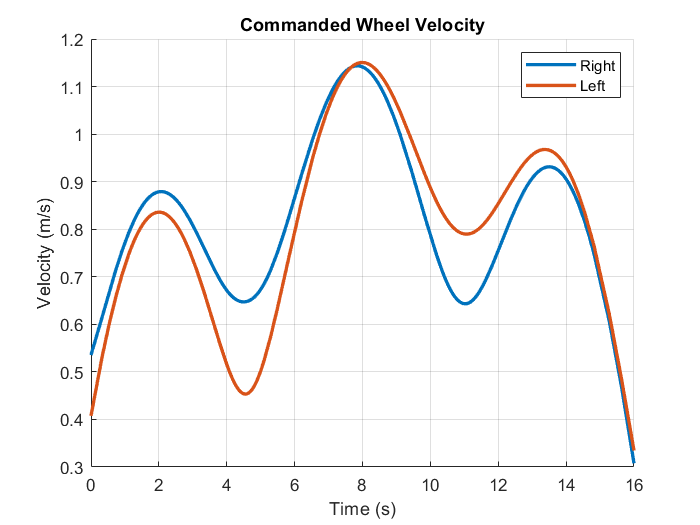


omega = cross(T_hat, dT_hat);

V_right = norm(v) + omega(3) .* (diam/2);
V_left = norm(v) - omega(3) .* (diam/2);


figure(2)
clf
hold on
fplot(V_right, [0,16], "Linewidth", 2)
fplot(V_left, [0,16], "Linewidth", 2)
title("Commanded Wheel Velocity")
xlabel("Time (s)")
ylabel("Velocity (m/s)")
hold off
legend("Right", "Left")

grid on

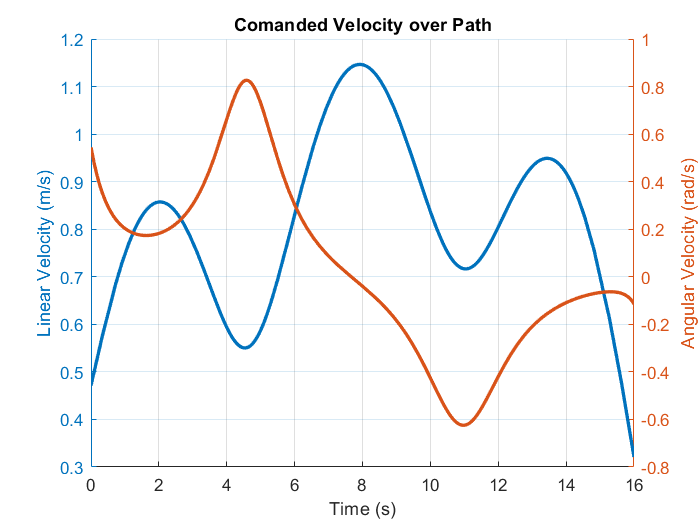

figure()
clf
hold on
title("Comanded Velocity over Path")
yyaxis left
fplot(norm(v), [0,16], "Linewidth", 2)
ylabel("Linear Velocity (m/s)")
yyaxis right
fplot(omega(3), [0,16], "Linewidth", 2)
ylabel("Angular Velocity (rad/s)")
xlabel("Time (s)")

grid on

hold off

figure()
clf
data = readtable("BoD_data")

data = 292×3 table
    time_seconds_    encoderLeft_meters_    encoderRight_meters_
    _____________    ___________________    ____________________
        102.3              18.743                   18.37       
        102.4              18.776                    18.4       
        102.5              18.809                   18.43       
        102.6              18.842                   18.46       
        102.7              18.875                  18.491       
        102.8              18.908                  18.521       
        102.9              18.941                  18.551       
          103              18.974                  18.581       
        103.1              19.007                  18.611       
        103.2               19.04                  18.642       
        103.3              19.073                  18.672       
        103.4              19.106 

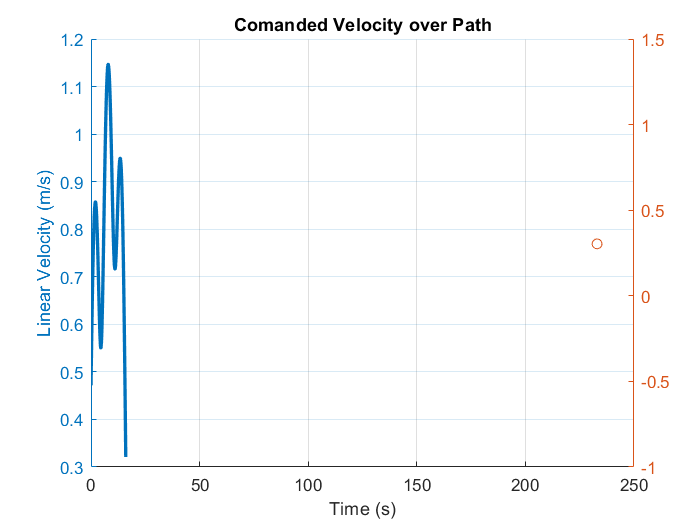


%hold on
%plot(reconstructed_vel(:,1))
%plot(reconstructed_vel(:,2))
%hold off
rt = eval(subs(r,t,0));
reconstructed_v = [0];
reconstructed_omega = [0];
reconstructed_vl = [0];
reconstructed_vr = [0];


heading = eval(subs(T_hat, t, 0));



theta = atan(heading(2) / heading(1));
for i = 73:233
    dt = data.time_seconds_(i) - data.time_seconds_(i-1);
    ddl = data.encoderLeft_meters_(i) - data.encoderLeft_meters_(i-1);
    ddr = data.encoderRight_meters_(i) - data.encoderRight_meters_(i-1);
    
    vl = ddl/dt;
    vr = ddr/dt;
    
    V = (vl+vr)/2;
    Omega = (vr-vl)/diam;
    theta = theta + Omega*dt;
    rtx = V*cos(theta)*dt;
    rty = V*sin(theta)*dt;
    reconstructed_omega(end+1) = Omega;
    reconstructed_v(end+1) = V;
    reconstructed_vl(end+1) = vl;
    reconstructed_vr(end+1) = vr;
    rt(end+1,:) = rt(end,:) + [rtx rty 0];
    scatter(i, V)

end
hold off

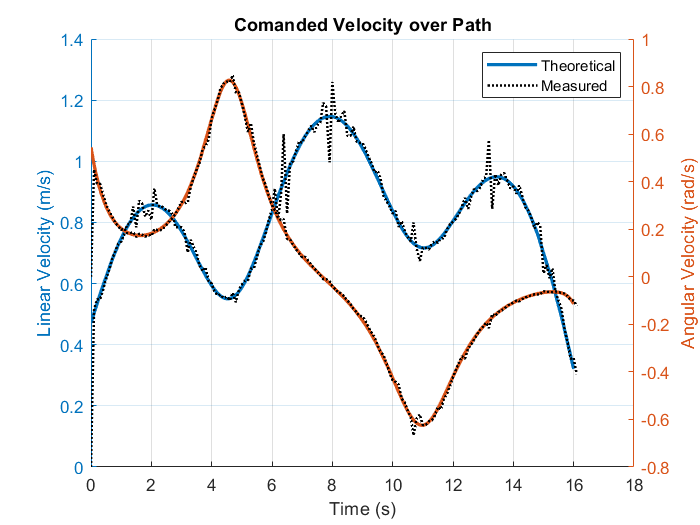

figure()
clf
hold on
title("Comanded Velocity over Path")
yyaxis left
hold on
fplot(norm(v), [0,16], "Linewidth", 2)
plot(data.time_seconds_(72:233) - data.time_seconds_(72), reconstructed_v, ":k", "Linewidth", 1.5)
hold off
ylabel("Linear Velocity (m/s)")
yyaxis right
hold on
fplot(omega(3), [0,16], "Linewidth", 2)
plot(data.time_seconds_(72:233) - data.time_seconds_(72), reconstructed_omega, ":k", "Linewidth", 1.5)
hold off
ylabel("Angular Velocity (rad/s)")
xlabel("Time (s)")

legend("Theoretical", "Measured")
grid on

hold off

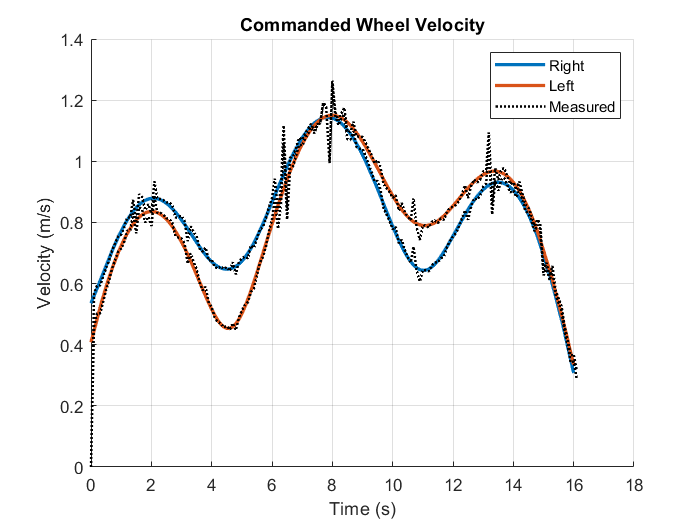

omega = cross(T_hat, dT_hat);

V_right = norm(v) + omega(3) .* (diam/2);
V_left = norm(v) - omega(3) .* (diam/2);


figure(2)
clf
hold on
fplot(V_right, [0,16], "Linewidth", 2)
fplot(V_left, [0,16], "Linewidth", 2)
plot(data.time_seconds_(72:233) - data.time_seconds_(72), reconstructed_vl, ":k", "Linewidth", 1.5)
plot(data.time_seconds_(72:233) - data.time_seconds_(72), reconstructed_vr, ":k", "Linewidth", 1.5)
title("Commanded Wheel Velocity")
xlabel("Time (s)")
ylabel("Velocity (m/s)")
hold off
legend("Right", "Left", "Measured")

grid on

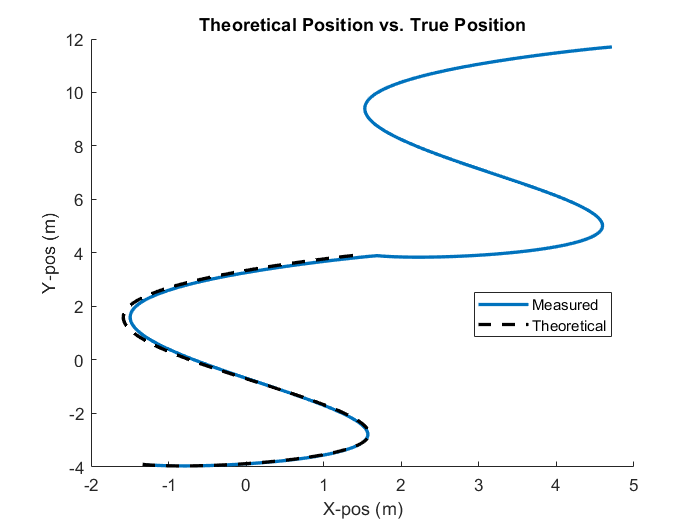


figure()
clf
hold on
plot(rt(:, 1), rt(:, 2), "Linewidth", 2)
plot(R(1,:), R(2,:),'k--', "Linewidth", 2)
xlabel("X-pos (m)")
ylabel("Y-pos (m)")
title("Theoretical Position vs. True Position")
legend("Measured","Theoretical",  "Location", "Best")